# Bifurcation diagram for a Y-shaped quantum graph

We use 

- Six programs from the directory `source/continuation` which an end-user may simply run themselves

- Two programs from `source/examples` which an end-user could copy in creating their own project

## Construct the quantum graph and find the first few eigenfunctions

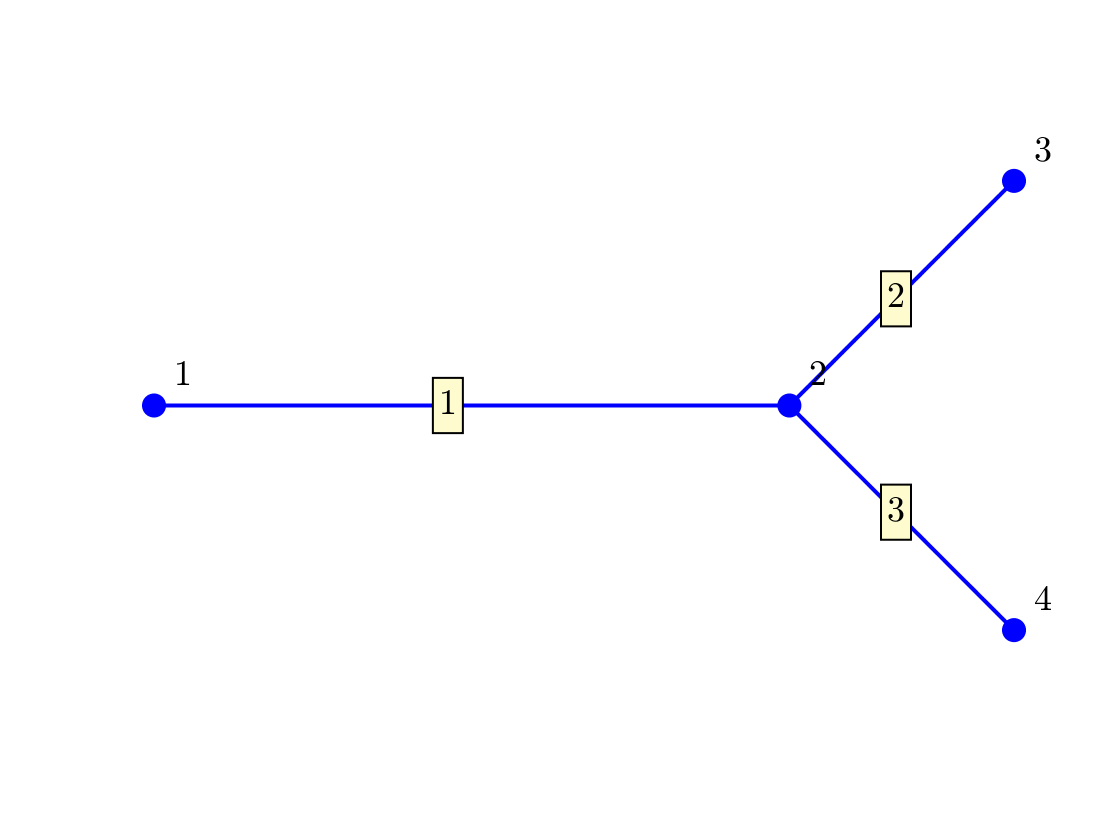

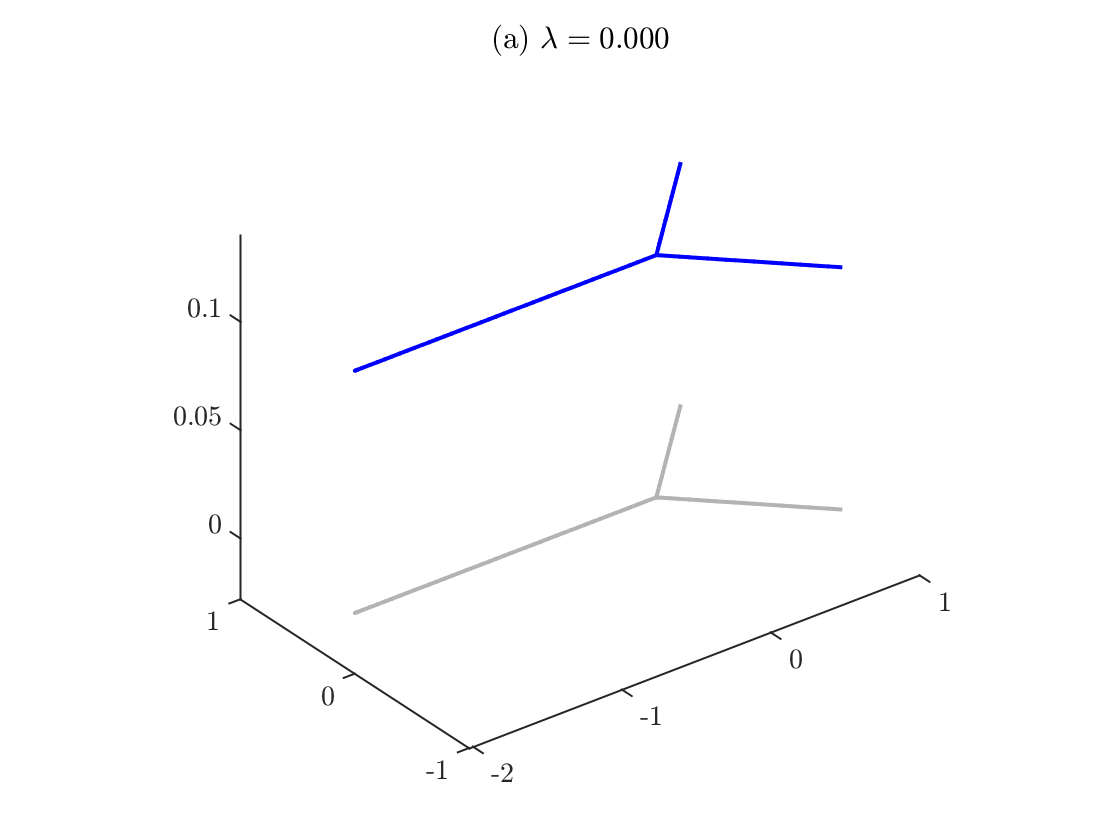

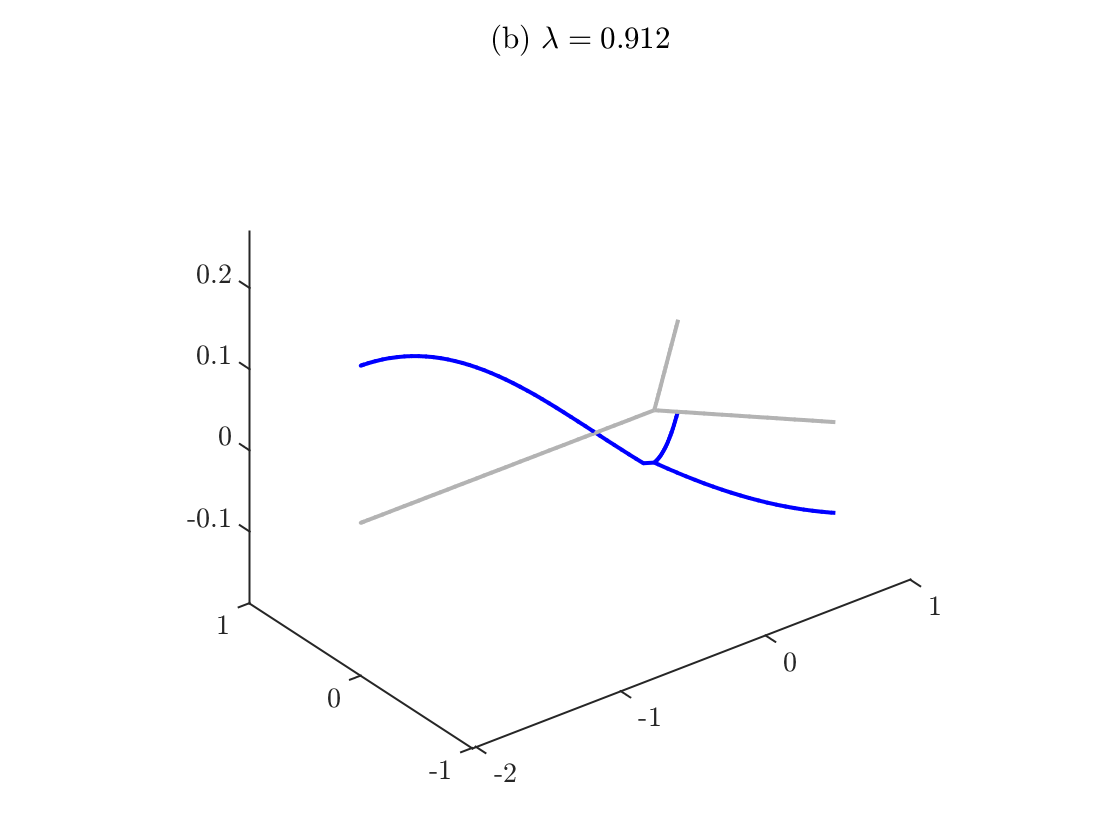

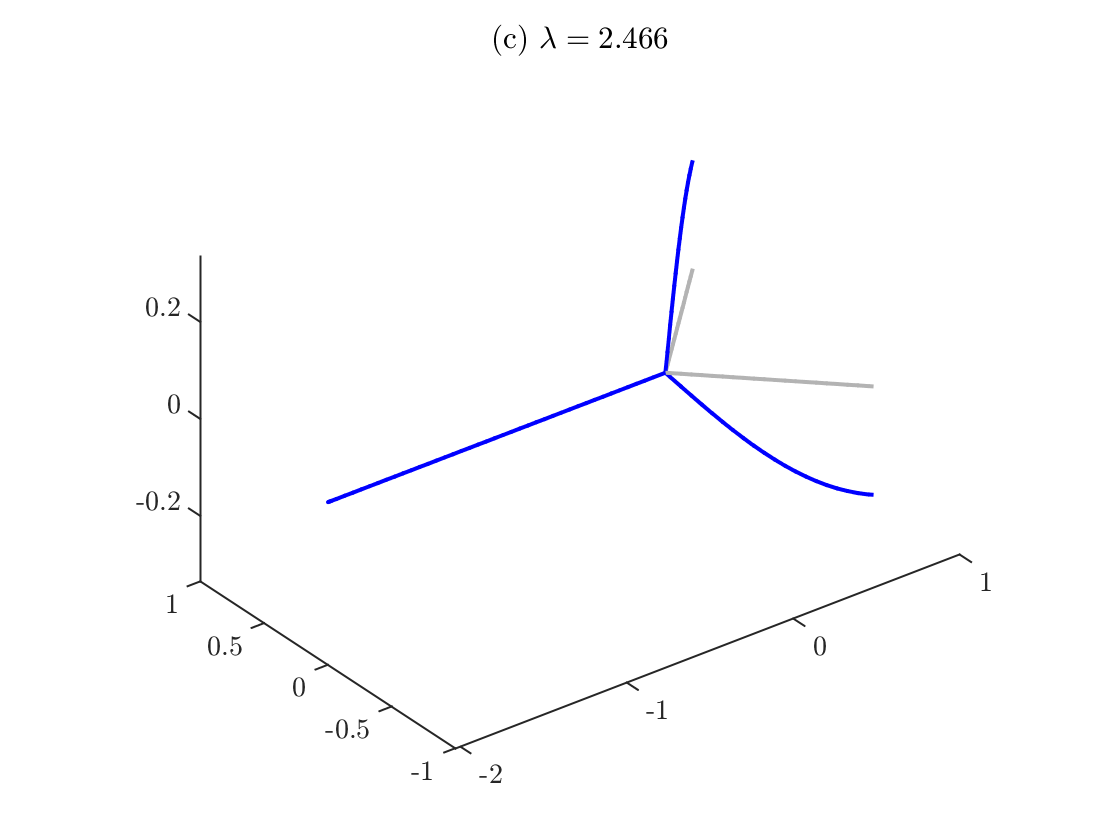

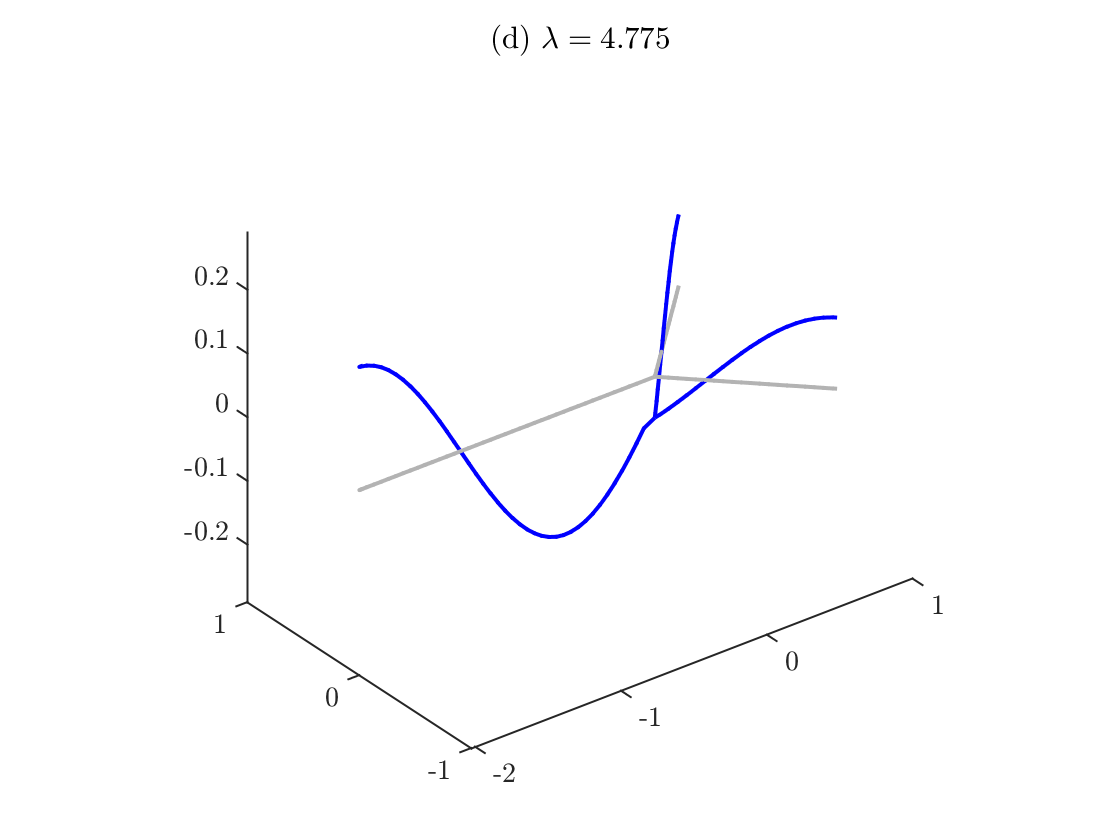

Saved to directory data/yShape/013.
Run number is 13.


tag='yShape';
LVec=[2 1 1];
nXVec=[40 20 20];
robinCoeff=[];
nToPlot=4;
nDoubles=2;
nTriples=0;
diagramNumber=eigenfunctionsSaveData(tag,LVec,nXVec,robinCoeff,nToPlot,nDoubles,nTriples);

## Compute a branch that is a continuation of the ground state eigenfunction

- The function `continuerSet` acts like the MATLAB functions `odeset` and `optimset.` It sets a number of options that are used by the continuation programs

- The function `continueFromEig` continues a branch from the linear limit of an eigenfunction computed in the previous step

options=continuerSet([],'LambdaThresh',-2,'NThresh',6,'plotFlag',false);
[bn1,bl1]=continueFromEig(tag,diagramNumber,1,options);

Lambda threshold crossed.
Branch number 1.
Data saved to directory data/yShape/013/branch001.
Branching Bifurcation at solution number 10.
Branching Bifurcation at solution number 15.


## Compute some branches that bifurcate from this first branch

- The function `continueFromBranchpoint` continues a branch from the first branching bifurcation point. Since this is a symmetry-breaking bfirucation, we only need to continue in one direction, the branch stored in `bn3` at bifurcation location` bl1(2)`

[bn2,bl2]=continueFromBranchPoint(tag,diagramNumber,bn1,bl1(1),1,options);

Lambda threshold crossed.
Branch number 2.
Data saved to directory data/yShape/013/branch002.
No branching bifurcations found.


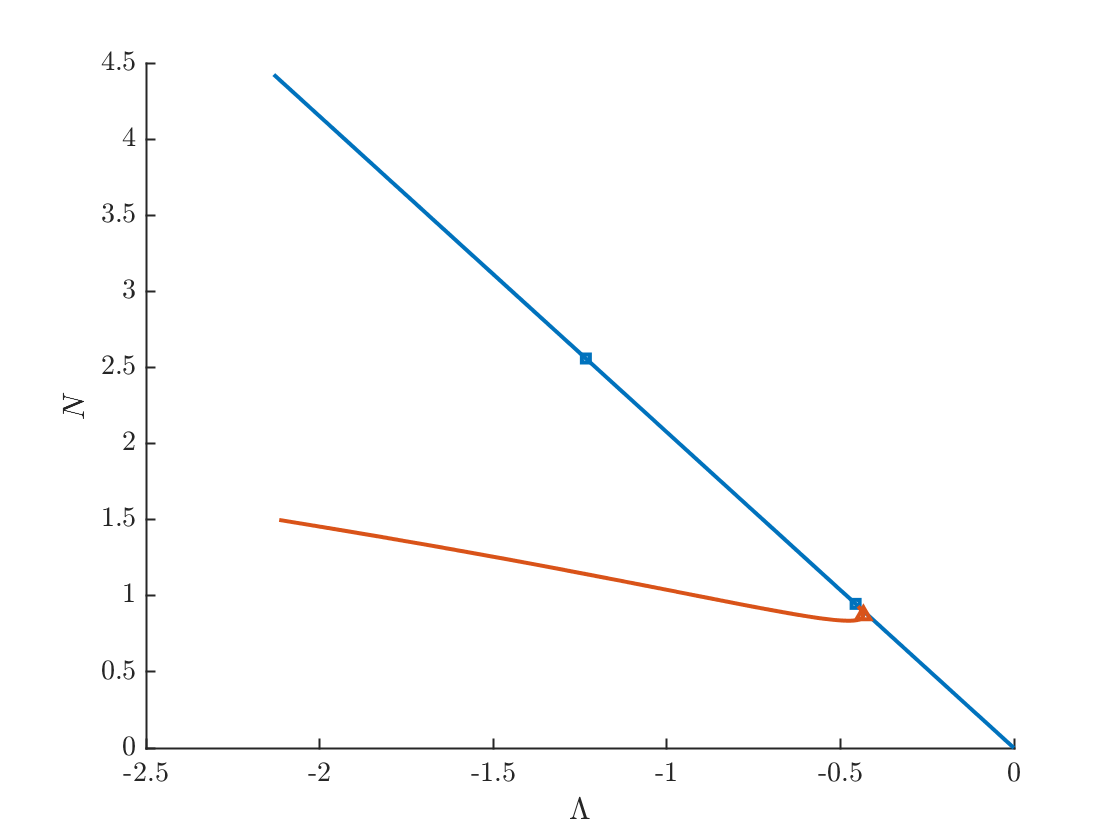

bifurcationDiagram(tag,diagramNumber)

- The function `continueFromBranchpoint` continues a branch from the first branching bifurcation point. Since this is a transcritical bfirucation, we need to continue in both directions, the branch stored in `bn3` at bifurcation location` bl1(2)`

[bn3,bl3]=continueFromBranchPoint(tag,diagramNumber,bn1,bl1(1),-1,options);

Lambda threshold crossed.
Branch number 3.
Data saved to directory data/yShape/013/branch003.
Branching Bifurcation at solution number 11.


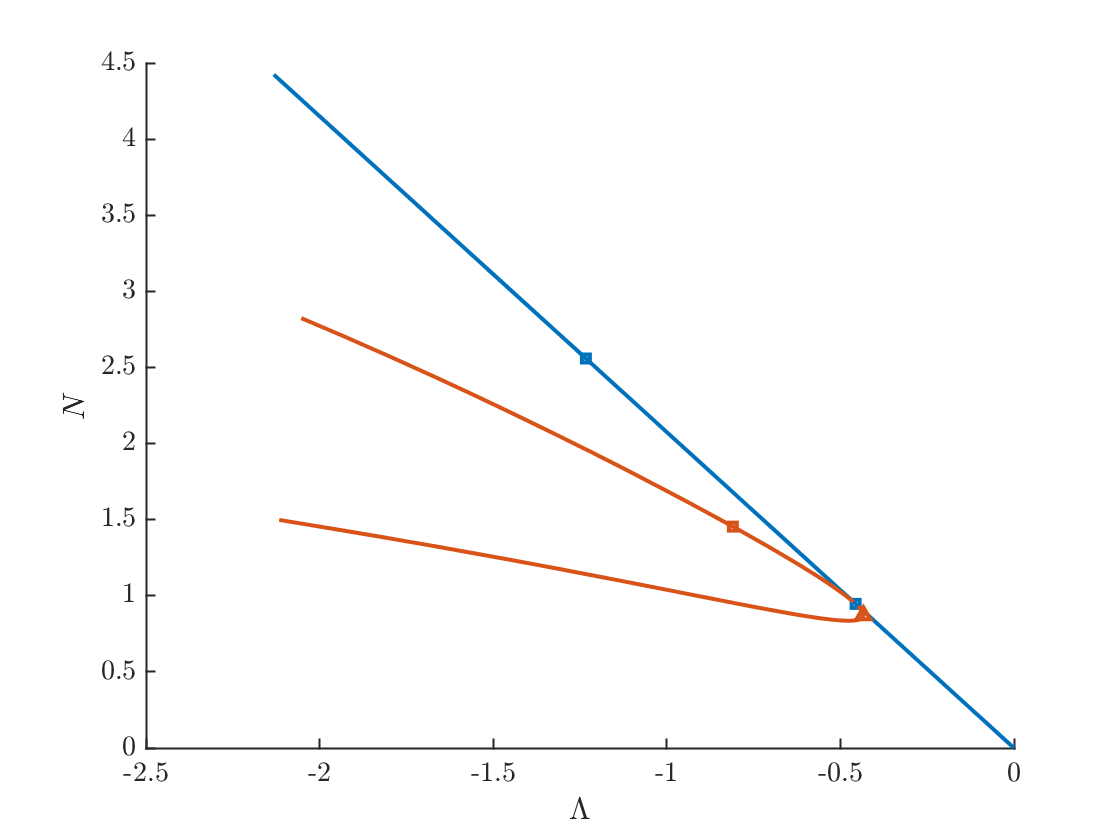

bifurcationDiagram(tag,diagramNumber)

[bn4,bl4]=continueFromBranchPoint(tag,diagramNumber,bn1,bl1(2),-1,options);

Lambda threshold crossed.
Branch number 4.
Data saved to directory data/yShape/013/branch004.
No branching bifurcations found.


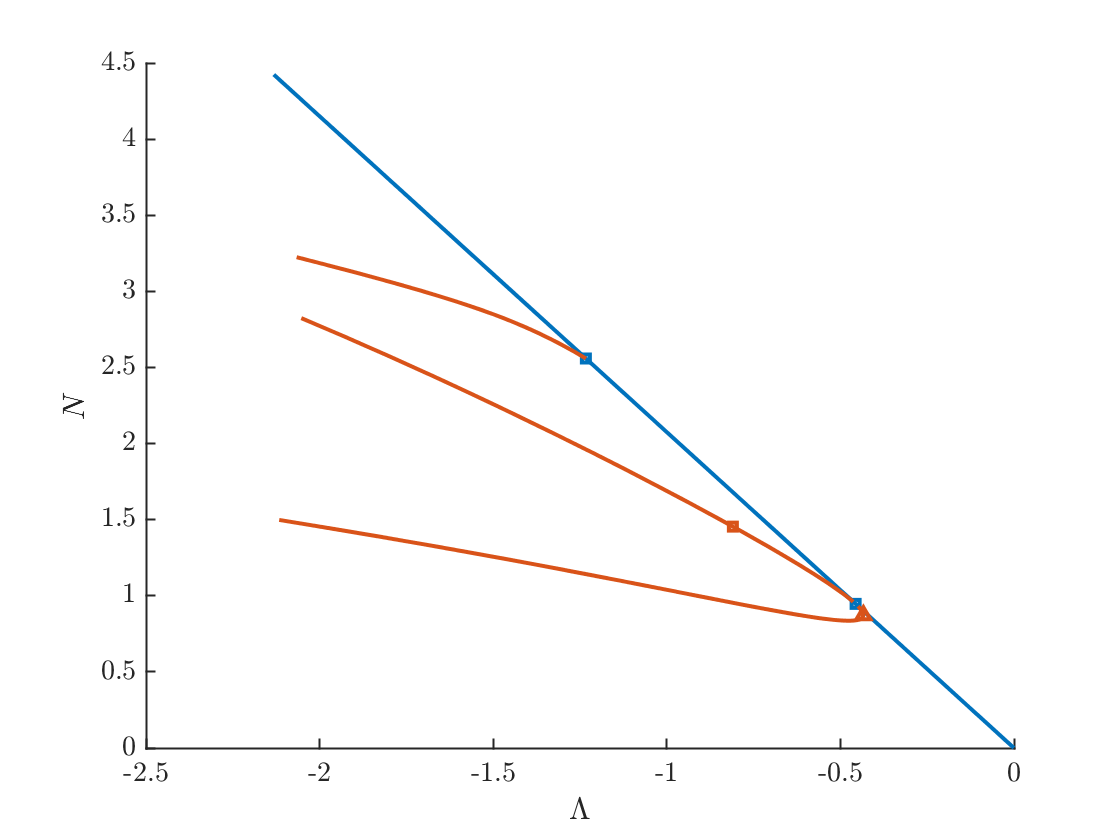

bifurcationDiagram(tag,diagramNumber)

## Compute a branch that bifurcates from the second branch

Continues from the branch stored in `bn3` from the bifurcation point at `bl3(1)`

[bn5,bl5]=continueFromBranchPoint(tag,diagramNumber,bn3,bl3(1),1,options);

Lambda threshold crossed.
Branch number 5.
Data saved to directory data/yShape/013/branch005.
No branching bifurcations found.


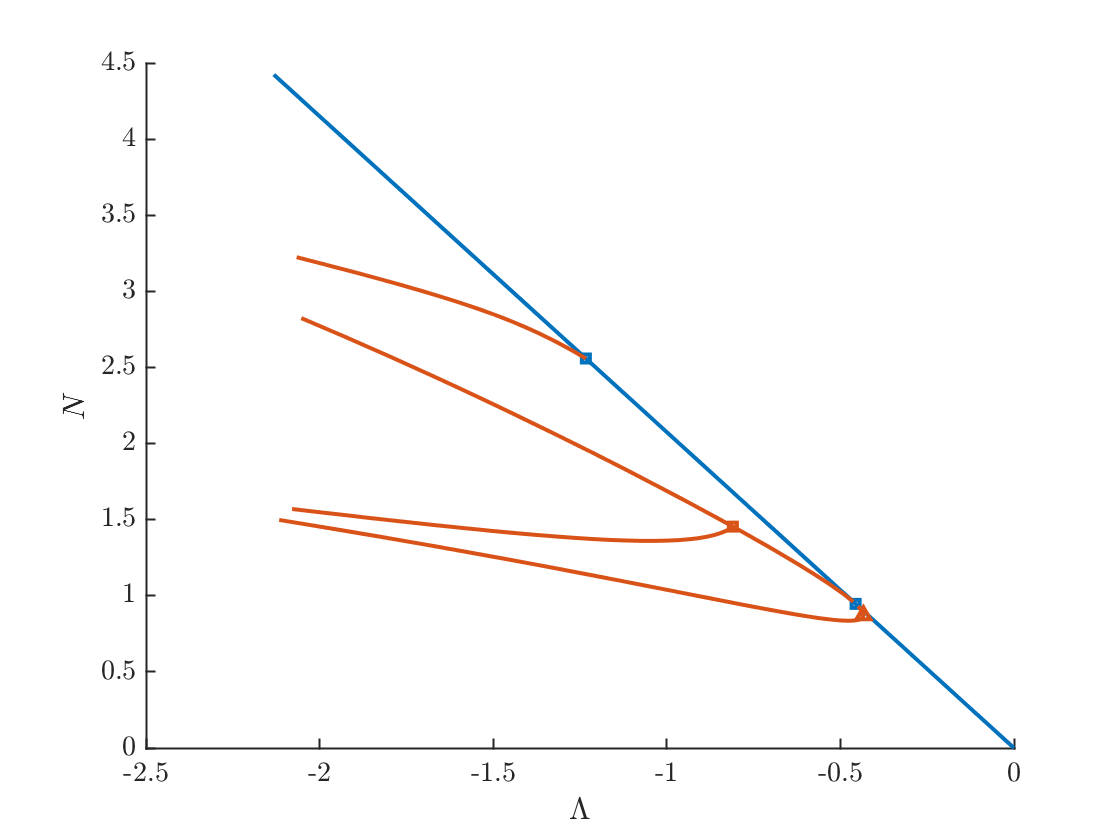

bifurcationDiagram(tag,diagramNumber)

## Plot some solutions

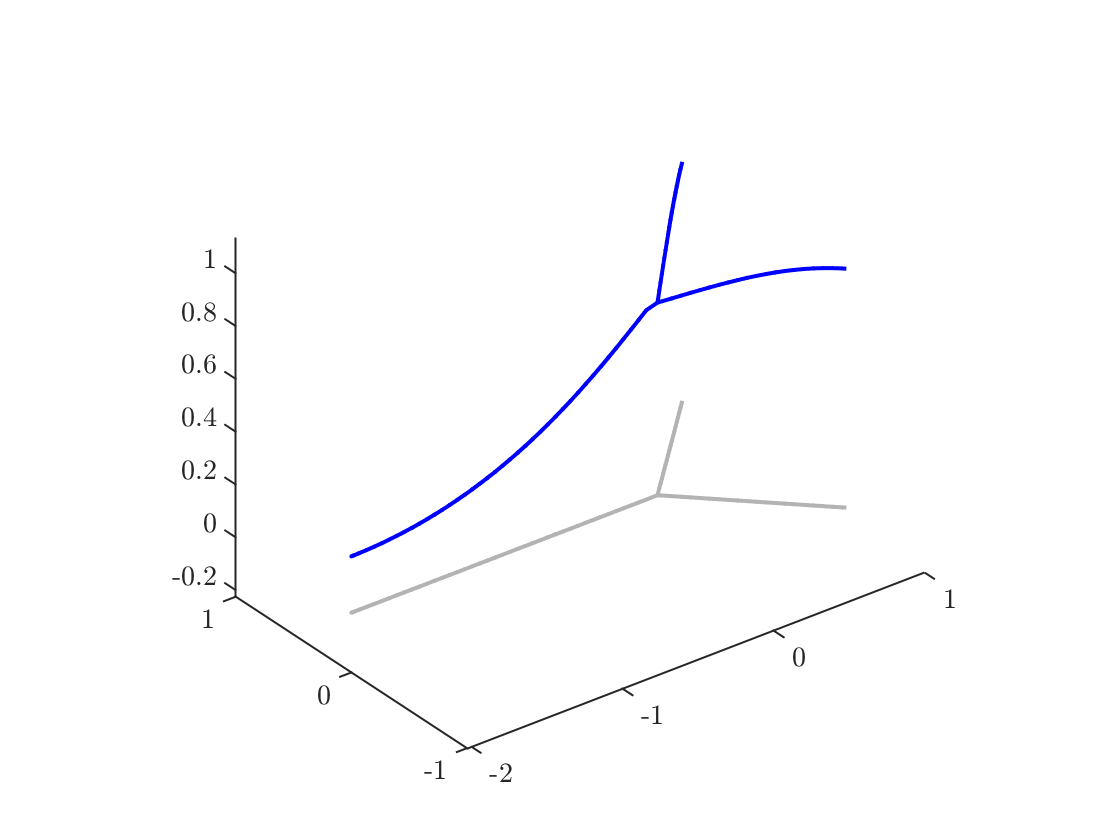

plotSolution(tag,diagramNumber,bn3,15)

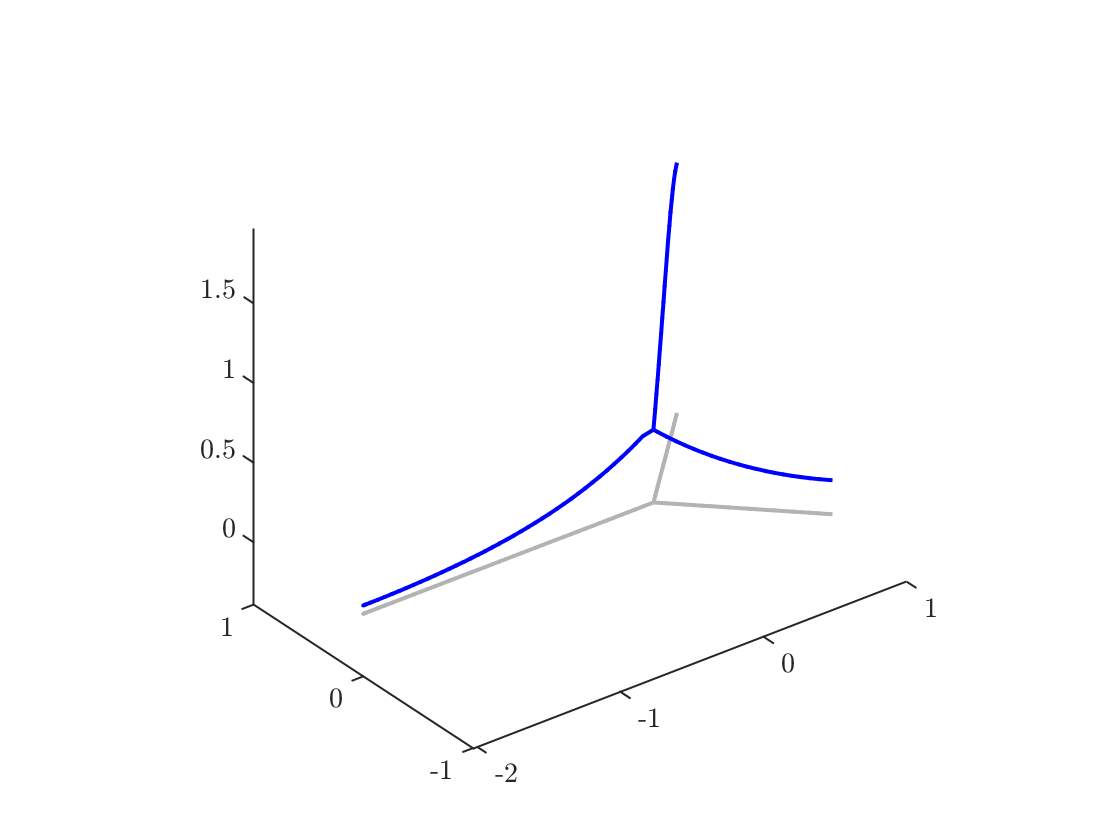

plotSolution(tag,diagramNumber,bn5,'last')